path = 'D:\桌面\image_3.tif'

path = 'D:\桌面\image_3.tif'

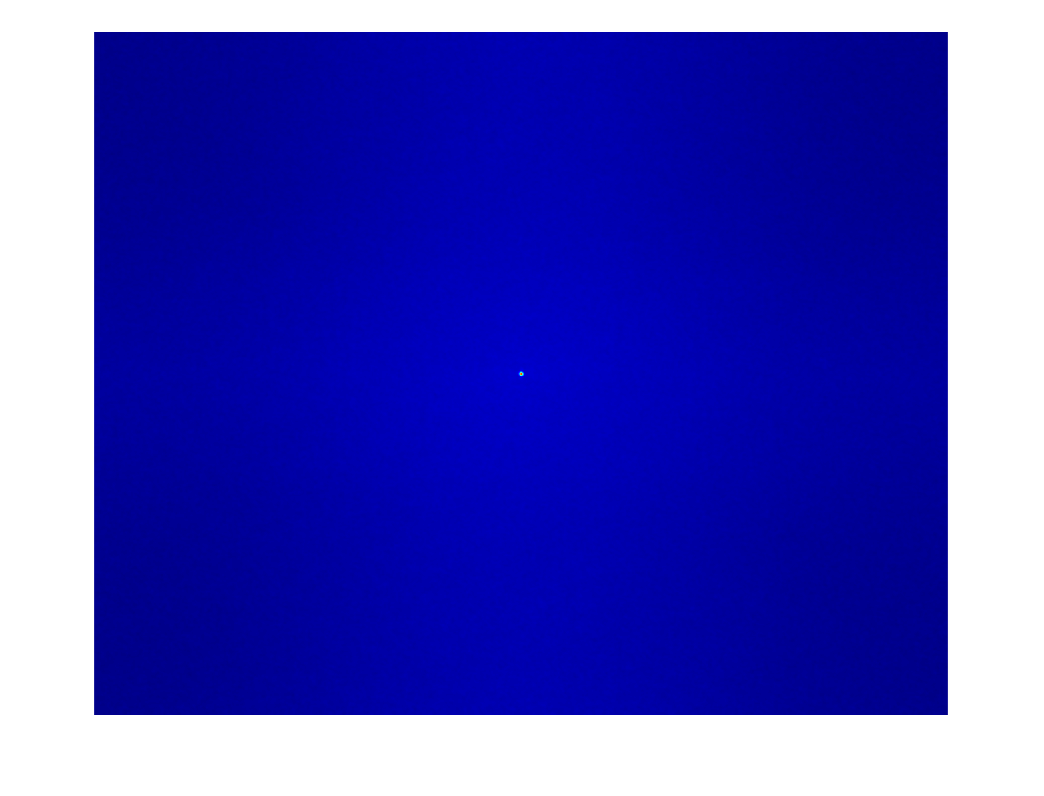

image = imread(path);
image = rgb2gray(image(:, :, (1:3)));
ac = abs(fftshift(ifft2(abs(fftshift(fft2(image))).^2)));
figure;
imshow(ac, []);
colormap Jet;

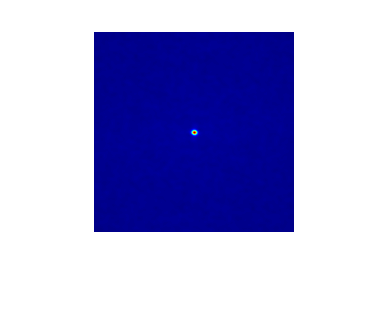


[r, c] = size(ac);
s = 200;
ac1 = ac((r/2-s/2+1 : r/2+s/2), (c/2-s/2+1 : c/2+s/2));
aq = ac1 - min(ac1, [], "all");
figure;
imshow(aq, []);
colormap Jet;